# Cassini-Huygens Spacecraft

Instructions are in the task pane to the left. Complete and submit each task one at a time.

## Task 1

The file `cassini.txt` contains data on the location of the Cassini-Huygens spacecraft for the first several years of the probe's mission. In this project, you'll visualize the position of the spacecraft around the sun.

[https://omniweb.gsfc.nasa.gov/coho/helios/heli.html](https://omniweb.gsfc.nasa.gov/coho/helios/heli.html)

cassini = readtable("./data/cassiniData.csv", "TextType", "string");
planets = readtable("./data/planetData.csv", "TextType", "string");

## Task 2

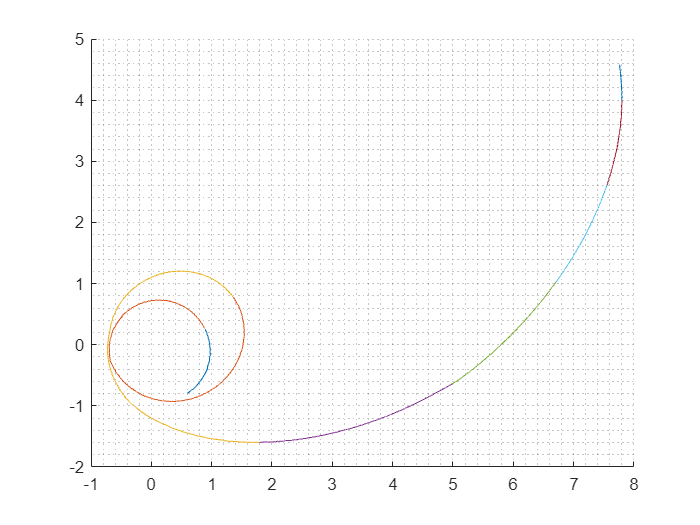

hold on
grid minor
for k = min(cassini.yr):max(cassini.yr)
    plot(cassini.x(cassini.yr==k), cassini.y(cassini.yr==k))
end
hold off

## Task 3

The table `planets` contains the orbital radius of each of the eight planets in our solar system. You can use the radius to add orbits to your plot.

To plot a circle of radius *r*, create a vector of angles from 0 to 2*π*. Then create the *x*-*y* data for the plot using the following formulas:

*x *= *r*cos(*θ*),    *y *= *r*sin(*θ*)

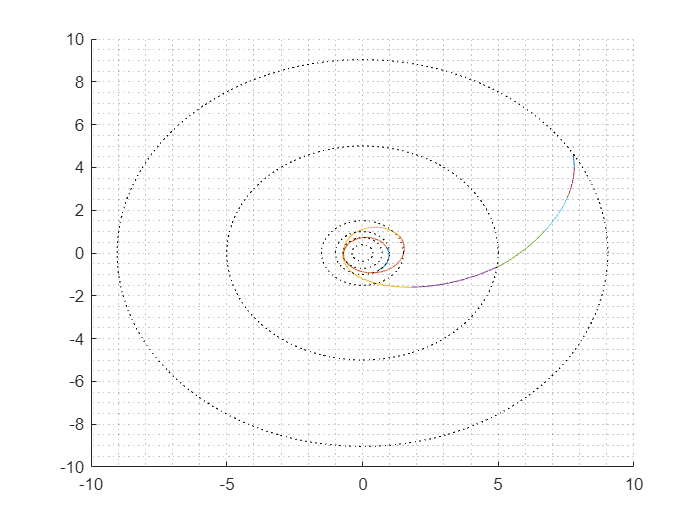

theta = linspace(0, 2*pi);
hold on
for k = 1:6
    plot(planets.Radius(k)*cos(theta), planets.Radius(k)*sin(theta), "k:")
end
hold off

## Task 4

Notice in your plot that the spacecraft can be in a planet's orbit for multiple days. How many days did it spend in the orbit of each planet?

You can find the distance of the spacecraft from the sun using its *x-y-z* data in the table `cassini`.


$$d=\sqrt{x^2 +y^2 +z^2 }$$


d = round(sqrt(cassini.x.^2 + cassini.y.^2 + cassini.z.^2), 2);
t = zeros(length(planets.Radius), 1);
for k = 1:length(planets.Radius)
    t(k) = nnz(d == planets.Radius(k));
end
planets.Days = t

planets = 8×3 table
      Name       Radius    Days
    _________    ______    ____

    "Mercury"     0.39       0 
    "Venus"       0.72      16 
    "Earth"          1      19 
    "Mars"        1.51       9 
    "Jupiter"        5       2 
    "Saturn"      9.04       2 
    "Uranus"     19.18       0 
    "Neptune"    30.06       0 
